clear all
x1 = 200;
x2 = 650;
[pathsSpikes tmp] = ReadPCAPaths('D:\Jazmin\MultichannelDataTanks\HIP\');
%Obtains the paths to all the content in the specified path

[DataTable] = ReadUnitTableMultichannel("A2",1,'D:\Jazmin\MultichannelDataTanks\HIP\MultichannelHipppocampusdata.xlsx');
%read the excel table and saves it in a variable

[pathsSpikesMultichannel] = pathsMultichannel(tmp,pathsSpikes,DataTable);
%It creates the path to the units inlcuded in the excel table

[BST, BST_MUA] = ExtractDataMultiChannel(DataTable,pathsSpikesMultichannel); %It gets a structure wiht all the BST

UN = load ('D:\Jazmin\MultichannelDataTanks\HIP\spiketable_Aud_Sig.mat');
MUA = load ('D:\Jazmin\MultichannelDataTanks\HIP\spiketable_Aud_Sig_MUA.mat');
% UN.spiketable.unitloc = [];
SpiketableComplete = [UN.spiketable;MUA.spiketable];
%It contains structures with all the units that have an auditory response

load('C:\Jazmin\HIP\CompleteSpikes.mat')
load('C:\Jazmin\HIP\CompleteSpikes_MUA.mat')

%Add a sweep identifier 1 to 400 for each trial
for i = 1:1:size(BST,1)
    y = 0;
    for j = 2:1:3060
        if BST(i).bst.Epocs.Values.wfrq(j-1,1) == 100 && BST(i).bst.Epocs.Values.wfrq(j,1) > 100
            BST(i).bst.Epocs.Values.swee(j:j+399,1) = [1:400]';
        end
    end
end


%These section creates a vector for each recording with the row number
%where each kind of stimulus of interest happen and saves it in a structure
for i = 1:1:size(BST,1)
    ODDTrialIndex = zeros(80,1);
    ODDTrialIndexP = zeros(80,1);
    CTR_ASCTrialIndex = zeros(160,1);
    CTRMSTrialIndex_F1 = zeros(160,1);
    STDMSTrialIndex = zeros(80,1);
    STDTrialIndex = zeros(80,1);
    AllSTDTrialIndex = zeros(360,1);
    AllSTDTrialIndexP = zeros(360,1);
    n = 1;
    m = 1;
    mn = 1;
    mm = 1;
    mp = 1;
    k = 1;
    p = 1;
    pp = 1;
    t = 1;
    tt = 1;
    q = 1;
    r = 1;
    s = 0;
    for j = 1:1:3060
        if isempty(cell2mat(BST(i).bst.Epocs.Values.type(j,1)))
            s = s + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            ODDtrials(n,1) = BST(i).bst.Epocs.Values.swee(j,1);
            ODDTrialIndex(n,1) = j;
            n = n + 1;
            %        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            %     %             ODDtrials(n,1) = BST(i).bst.Epocs.Values.swee(j,1) + 1;
            %                 ODDTrialIndexP(q,1) = j;
            %                 q = q + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-ASC-F1');
            CTR_ASC_F1trials(m,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_ASC_F1TrialIndex(m,1) = j;
            m = m + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-ASC-F2');
            CTR_ASC_F2trials(mn,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_ASC_F2TrialIndex(mn,1) = j;
            mn = mn + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-DES-F1');
            CTR_DESC_F1trials(mm,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_DESC_F1TrialIndex(mm,1) = j;
            mm = mm + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-DES-F2');
            CTR_DESC_F2trials(mp,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_DESC_F2TrialIndex(mp,1) = j;
            mp = mp + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'MS-F1');
            CTRMStrials_F1(t,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTRMSTrialIndex_F1(t,1) = j;
            t = t + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'MS-F2');
            CTRMStrials_F2(tt,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTRMSTrialIndex_F2(tt,1) = j;
            tt = tt + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'STD')
            STDtrials(k,1) = BST(i).bst.Epocs.Values.swee(j,1);
            STDTrialIndex(k,1) = j;
            k = k + 1;
        end

    end

    for iii = 21:1:1740

        % if isempty(cell2mat(BST(i).bst.Epocs.Values.type(iii,1))) && BST(i).bst.Epocs.Values.wfrq(iii,1)>100
        % 
        %     AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
        %     AllSTDTrialIndex(p,1) = iii;
        %     p = p + 1;
       if contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDR') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'')
           AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndex(p,1) = iii;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDR') | contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'STD') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'ODDR')
            AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndex(p,1) = iii;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDP') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'')
            AllSTDtrialsP(pp,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndexP(pp,1) = iii;
            pp = pp + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDP') | contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'STD') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'ODDP')
            AllSTDtrialsP(pp,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndexP(pp,1) = iii;
            pp = pp + 1;
        end
    end

    ODDTrialIndexP = [ODDTrialIndex(41:80);ODDTrialIndex(121:160)];
    ODDTrialIndex = [ODDTrialIndex(1:40);ODDTrialIndex(81:120)];
    STDTrialIndexP = [ STDTrialIndex(41:80); STDTrialIndex(121:160)];
    STDTrialIndex = [ STDTrialIndex(1:40); STDTrialIndex(81:120)];

    ODDtrialsP = [ODDtrials(41:80);ODDtrials(121:160)];
    ODDtrials = [ODDtrials(1:40);ODDtrials(81:120)];
    STDtrialsP = [ STDtrials(41:80); STDtrials(121:160)];
    STDtrials = [ STDtrials(1:40); STDtrials(81:120)];

    ODDTrialIndexS = struct('ODDTrialIndex', ODDTrialIndex);
    ODDTrialIndexPS = struct('ODDTrialIndexP', ODDTrialIndexP);
    CTR_DESC_F2TrialIndexS = struct('CTRTrialIndex', CTR_DESC_F2TrialIndex);
    CTR_DESC_F1TrialIndexS = struct('CTRTrialIndex', CTR_DESC_F1TrialIndex);
    CTR_ASC_F1TrialIndexS = struct('CTRTrialIndex', CTR_ASC_F1TrialIndex);
    CTR_ASC_F2TrialIndexS = struct('CTRTrialIndex', CTR_ASC_F2TrialIndex);
    CTRMSTrialIndexS_F1 = struct('CTRMSTrialIndex', CTRMSTrialIndex_F1);
    CTRMSTrialIndexS_F2 = struct('CTRMSTrialIndex', CTRMSTrialIndex_F2);
    STDTrialIndexS = struct('STDTrialIndex', STDTrialIndex);
    STDTrialIndexSP = struct('STDTrialIndex', STDTrialIndexP);
    AllSTDTrialIndexS = struct('AllSTDTrialIndex', AllSTDTrialIndex);
    AllSTDTrialIndexPS = struct('AllSTDTrialIndexP', AllSTDTrialIndexP);

    ODDTrialsS = struct('ODDtrials', ODDtrials);
    CTR_ASC_F1TrialsS = struct('CTRtrials', CTR_ASC_F1trials);
    CTR_ASC_F2TrialsS = struct('CTRtrials', CTR_ASC_F2trials);
    CTR_DESC_F1TrialsS = struct('CTRtrials', CTR_DESC_F1trials);
    CTR_DESC_F2TrialsS = struct('CTRtrials', CTR_DESC_F2trials);
    CTRMSTrialsS_F1 = struct('CTRMStrials', CTRMStrials_F1);
    CTRMSTrialsS_F2 = struct('CTRMStrials', CTRMStrials_F2);
    STDTrialsS = struct('STDtrials', STDtrials);
    STDTrialsSP = struct('STDtrials', STDtrialsP);
    ODDTrialsPS = struct('ODDtrialsP', ODDtrialsP);
    AllSTDTrialsS = struct('AllSTDtrials', AllSTDtrials);
    AllSTDTrialsPS = struct('AllSTDtrialPs', AllSTDtrialsP);

    ODDTrialIndexComplete(:,i) = ODDTrialIndexS;
    ODDTrialIndexCompleteP(:,i) = ODDTrialIndexPS;
    CTR_ASC_F1TrialIndexComplete(:,i) = CTR_ASC_F1TrialIndexS;
    CTR_ASC_F2TrialIndexComplete(:,i) = CTR_ASC_F2TrialIndexS;
    CTR_DESC_F1TrialIndexComplete(:,i) = CTR_DESC_F1TrialIndexS;
    CTR_DESC_F2TrialIndexComplete(:,i) = CTR_DESC_F2TrialIndexS;
    CTRMSTrialIndex_F1Complete(:,i) = CTRMSTrialIndexS_F1;
    CTRMSTrialIndex_F2Complete(:,i) = CTRMSTrialIndexS_F2;
    STDTrialIndexComplete(:,i) = STDTrialIndexS;
    STDTrialIndexComplete_P(:,i) = STDTrialIndexSP;
    AllSTDTrialIndexComplete(:,i) = AllSTDTrialIndexS;
    AllSTDTrialIndexCompleteP(:,i) = AllSTDTrialIndexPS;

    ODDTrialsComplete(:,i) = ODDTrialsS;
    ODDTrialsCompleteP(:,i) = ODDTrialsPS;
    CTR_ASC_F1TrialsComplete(:,i) = CTR_ASC_F1TrialsS;
    CTR_ASC_F2TrialsComplete(:,i) = CTR_ASC_F2TrialsS;
    CTR_DESC_F1TrialsComplete(:,i) = CTR_DESC_F1TrialsS;
    CTR_DESC_F2TrialsComplete(:,i) = CTR_DESC_F2TrialsS;
    CTRMSTrialsComplete_F1(:,i) = CTRMSTrialsS_F1;
    CTRMSTrialsComplete_F2(:,i) = CTRMSTrialsS_F2;
    STDTrialsComplete(:,i) = STDTrialsS;
    STDTrialsComplete_P(:,i) = STDTrialsSP;
    AllSTDTrialsComplete(:,i) = AllSTDTrialsS;
    AllSTDTrialsCompleteP(:,i) = AllSTDTrialsPS;
end

for ii = 1:size(BST_MUA,1)
    AllSTDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialIndexCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
    CTRTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    CTRMSTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialIndexComplete_P(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialIndexCompleteP(ii).path = pathsSpikesMultichannel(ii,1);

    ODDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialsCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
    CTRTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    CTRMSTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialsComplete_P(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialsCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
end

AllSpikeTable = [CompleteSpikes;CompleteSpikes_MUA];
a = 1;
b = 1;
c = 1;
d = 1;
for i = 1:size(AllSpikeTable,1)
    if AllSpikeTable.Auditory(i) == 1
        AllSpikeTable_Auditory(a,:) = AllSpikeTable(i,:);
        a = a + 1;
    end
    if AllSpikeTable.AuditoryP(i) == 1
        AllSpikeTable_AuditoryP(b,:) = AllSpikeTable(i,:);
        b = b + 1;
    end
    if AllSpikeTable.Significance(i) == 1
        AllSpikeTable_Significance(c,:) = AllSpikeTable(i,:);
        c = c + 1;
    end
    if AllSpikeTable.SignificanceP(i) == 1
        AllSpikeTable_SignificanceP(d,:) = AllSpikeTable(i,:);
        d = d + 1;
    end
end

for i = 1:size(AllSpikeTable_Significance,1)
    AllSTDtrialsRest(i).STDtrials = setdiff(AllSTDTrialsComplete(1).AllSTDtrials(1:360),STDTrialsComplete(1).STDtrials(1:40));
    AllSTDtrialsRest_P(i).STDtrialsP = setdiff(AllSTDTrialsCompleteP(1).AllSTDtrialPs(1:360),STDTrialsComplete_P(1).STDtrials(1:40));
    AllCTRMSTrials=(1:400);
    MStrials = setdiff(AllCTRMSTrials',CTRMSTrialsComplete_F1(1).CTRMStrials);
    MStrialsRest(i).MStrials = setdiff(MStrials,CTRMSTrialsComplete_F2(1).CTRMStrials);
    AllCTRCASCascTrials=(1:400);
    CASCasctrials = setdiff(AllCTRCASCascTrials',CTR_ASC_F1TrialsComplete(1).CTRtrials);
    CASCasctrialsRest(i).CASCasctrials = setdiff(CASCasctrials,CTR_ASC_F2TrialsComplete(1).CTRtrials);
    AllCTRCASCdesTrials=(1:400);
    CASCdestrials = setdiff(AllCTRCASCdesTrials',CTR_DESC_F1TrialsComplete(1).CTRtrials);
    CASCdestrialsRest(i).CASCdes = setdiff(CASCdestrials,CTR_DESC_F2TrialsComplete(1).CTRtrials);
end

DEVcount = zeros(40,1);
    for j = 1:size(AllSpikeTable_Significance,1)
        for k = 1:1:40
            DEVtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,3));
            for i = 1:size(DEVtimesASC{1,1},1)
                if DEVtimesASC{1,1}(i) >= 200 && DEVtimesASC{1,1}(i) <= 650
                    DEVcount(k) = DEVcount(k) + 1;
                end
            end
    
            DEVtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,8));
            for i = 1:size(DEVtimesDES{1,1},1)
                if DEVtimesDES{1,1}(i) >= 200 && DEVtimesDES{1,1}(i) <= 650
                    DEVcount(k) = DEVcount(k) + 1;
                end
            end
        end
    end

STDcount = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,2));
        for i = 1:size(STDtimesASC{1,1},1)
            if STDtimesASC{1,1}(i) >= 200 && STDtimesASC{1,1}(i) <= 650
                STDcount(k) = STDcount(k) + 1;
            end
        end

        STDtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,7));
        for i = 1:size(STDtimesDES{1,1},1)
            if STDtimesDES{1,1}(i) >= 200 && STDtimesDES{1,1}(i) <= 650
                STDcount(k) = STDcount(k) + 1;
            end
        end
    end
end


STDcountRest = zeros(640,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:640
        STDtimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,1));
        for i = 1:size(STDtimesRest{1,1},1)
            if STDtimesRest{1,1}(i) >= 200 && STDtimesRest{1,1}(i) <= 650
                STDcountRest(k) = STDcountRest(k) + 1;
            end
        end
    end
end
STDcountRest = STDcountRest(1:320)+STDcountRest(321:640);

DEVcount_P = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        DEVtimesASC_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,6));
        for i = 1:size(DEVtimesASC_P{1,1},1)
            if DEVtimesASC_P{1,1}(i) >= 200 && DEVtimesASC_P{1,1}(i) <= 650
                DEVcount_P(k) = DEVcount_P(k) + 1;
            end
        end

        DEVtimesDES_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,10));
        for i = 1:size(DEVtimesDES_P{1,1},1)
            if DEVtimesDES_P{1,1}(i) >= 200 && DEVtimesDES_P{1,1}(i) <= 650
                DEVcount_P(k) = DEVcount_P(k) + 1;
            end
        end
    end
end

STDcount_P = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,5));
        for i = 1:size(STDtimesASC_P{1,1},1)
            if STDtimesASC_P{1,1}(i) >= 200 && STDtimesASC_P{1,1}(i) <= 650
                STDcount_P(k) = STDcount_P(k) + 1;
            end
        end

        STDtimesDES_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,9));
        for i = 1:size(STDtimesDES_P{1,1},1)
            if STDtimesDES_P{1,1}(i) >= 200 && STDtimesDES_P{1,1}(i) <= 650
                STDcount_P(k) = STDcount_P(k) + 1;
            end
        end
    end
end

STDcountRest_P = zeros(640,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:640
        STDtimesRest_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,4));
        for i = 1:size(STDtimesRest_P{1,1},1)
            if STDtimesRest_P{1,1}(i) >= 200 && STDtimesRest_P{1,1}(i) <= 650
                STDcountRest_P(k) = STDcountRest_P(k) + 1;
            end
        end
    end
end
STDcountRest_P = STDcountRest_P(1:320)+STDcountRest_P(321:640);

MScount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,13));
        for i = 1:size(MStimes_F1{1,1},1)
            if MStimes_F1{1,1}(i) >= 200 && MStimes_F1{1,1}(i) <= 650
                MScount_F1(k) = MScount_F1(k) + 1;
            end
        end
    end
end

MScount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,12));
        for i = 1:size(MStimes_F2{1,1},1)
            if MStimes_F2{1,1}(i) >= 200 && MStimes_F2{1,1}(i) <= 650
                MScount_F2(k) = MScount_F2(k) + 1;
            end
        end
    end
end

MScount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        MStimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,11));
        for i = 1:size(MStimesRest{1,1},1)
            if MStimesRest{1,1}(i) >= 200 && MStimesRest{1,1}(i) <= 650
                MScount_rest(k) = MScount_rest(k) + 1;
            end
        end
    end
end

CASCasccount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,15));
        for i = 1:size(CASCasctimes_F1{1,1},1)
            if CASCasctimes_F1{1,1}(i) >= 200 && CASCasctimes_F1{1,1}(i) <= 650
                CASCasccount_F1(k) = CASCasccount_F1(k) + 1;
            end
        end
    end
end

CASCasccount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,16));
        for i = 1:size(CASCasctimes_F2{1,1},1)
            if CASCasctimes_F2{1,1}(i) >= 200 && CASCasctimes_F2{1,1}(i) <= 650
                CASCasccount_F2(k) = CASCasccount_F2(k) + 1;
            end
        end
    end
end

CASCasccount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCasctimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,14));
        for i = 1:size(CASCasctimesRest{1,1},1)
            if CASCasctimesRest{1,1}(i) >= 200 && CASCasctimesRest{1,1}(i) <= 650
                CASCasccount_rest(k) = CASCasccount_rest(k) + 1;
            end
        end
    end
end

CASCdescount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,19));
        for i = 1:size(CASCdestimes_F1{1,1},1)
            if CASCdestimes_F1{1,1}(i) >= 200 && CASCdestimes_F1{1,1}(i) <= 650
                CASCdescount_F1(k) = CASCdescount_F1(k) + 1;
            end
        end
    end
end

CASCdescount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,18));
        for i = 1:size(CASCdestimes_F2{1,1},1)
            if CASCdestimes_F2{1,1}(i) >= 200 && CASCdestimes_F2{1,1}(i) <= 650
                CASCdescount_F2(k) = CASCdescount_F2(k) + 1;
            end
        end
    end
end

CASCdescount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCdestimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,17));
        for i = 1:size(CASCdestimesRest{1,1},1)
            if CASCdestimesRest{1,1}(i) >= 200 && CASCdestimesRest{1,1}(i) <= 650
                CASCdescount_rest(k) = CASCdescount_rest(k) + 1;
            end
        end
    end
end

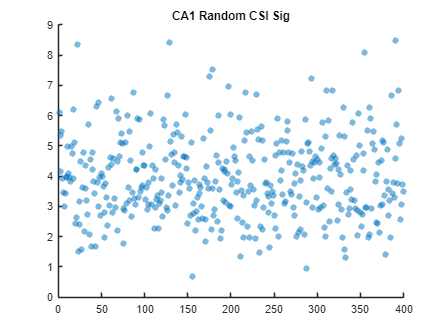

STD_CA1 = load('D:\Jazmin\MultichannelDataTanks\HIP\GranAverage\CA1 spikes per trial\ALLSTD');
DEV_CA1 = load('D:\Jazmin\MultichannelDataTanks\HIP\GranAverage\CA1 spikes per trial\ALLDEV');
CTR_CA1 = load('D:\Jazmin\MultichannelDataTanks\HIP\GranAverage\CA1 spikes per trial\ALLCTR');
STD_DG = load('D:\Jazmin\MultichannelDataTanks\HIP\GranAverage\DG spkies per trial\ALLSTD');
DEV_DG = load('D:\Jazmin\MultichannelDataTanks\HIP\GranAverage\DG spkies per trial\ALLDEV');
CTR_DG = load('D:\Jazmin\MultichannelDataTanks\HIP\GranAverage\DG spkies per trial\ALLCTR');
STD_CA1_mean = mean(STD_CA1.AllSTD,"omitnan"); 
DEV_CA1_mean = mean(DEV_CA1.AllDEV,"omitnan");
CTR_CA1_mean = mean(CTR_CA1.AllCTR,"omitnan");
STD_DG_mean = mean(STD_DG.AllSTD,"omitnan");
DEV_DG_mean = mean(DEV_DG.AllDEV,"omitnan");
CTR_DG_mean = mean(CTR_DG.AllCTR,"omitnan");

figure
scatter((1:400)',STD_CA1_mean,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
hold on
title ('CA1 Random CSI Sig')

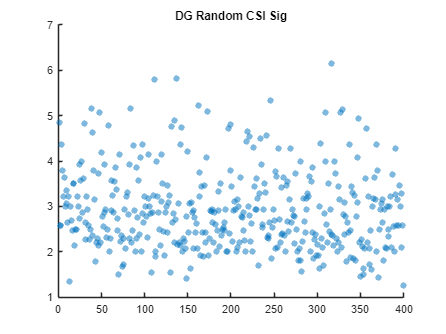


figure
scatter((1:400)',STD_DG_mean,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
hold on
title ('DG Random CSI Sig')


% % STD_CA1_nor = mean(STD_CA1.AllSTD,"omitnan")./max(STD_CA1_mean);
% % DEV_CA1_nor = mean(DEV_CA1.AllDEV,"omitnan")./max(STD_CA1_mean);
% % CTR_CA1_nor = mean(CTR_CA1.AllCTR,"omitnan")./max(STD_CA1_mean);
% % STD_DG_nor = mean(STD_DG.AllSTD,"omitnan")./max(STD_CA1_mean);
% % DEV_DG_nor = mean(DEV_DG.AllDEV,"omitnan")./max(STD_CA1_mean);
% % CTR_DG_nor = mean(CTR_DG.AllCTR,"omitnan")./max(STD_CA1_mean);

% ylim([0 1])
% scatter(DEV_CA1.DEV(:,1),DEV_CA1.DEV(:,2),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
        % 
        % p = polyfit(STD_CA1.STD(:,1),STD_CA1.STD(:,2), 1);
        % px = [min(STD_CA1.STD(:,1)) max(STD_CA1.STD(:,1))];
        % py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
        % 
        % p = polyfit(DEV_CA1.DEV(:,1),DEV_CA1.DEV(:,2), 1);
        % px = [min(DEV_CA1.DEV(:,1)) max(DEV_CA1.DEV(:,1))];
        % py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

STDcount_10 = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,2));
        for i = 1:size(STDtimesASC{1,1},1)
            if STDtimesASC{1,1}(i) >= 200 && STDtimesASC{1,1}(i) <= 650
                STDcount_10(k,j) = STDcount_10(k,j) + 1;
            end
        end

        STDtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,7));
        for i = 1:size(STDtimesDES{1,1},1)
            if STDtimesDES{1,1}(i) >= 200 && STDtimesDES{1,1}(i) <= 650
                STDcount_10(k,j) = STDcount_10(k,j) + 1;
            end
        end
    end
end
% STDcount_10_sum = sum(STDcount_10');


CA1_MC = STDcount_10(:,[1:5])';
CA1_Total = [CA1_MC(:,[1:10]);STD_CA1.AllSTD(:,[1:10])]

CA1_Total =      0     0     0     0     0     1     4     0     0     0
     0     0     0     0     0     1     2     0     1     0
     5     5     5     5     5     6     6     4     3     5
     0     1     0     0     0     0     0     3     0     0
     0     0     2     5     0     6     6     5     5     6
     0     0     0     0     2     0     0     0     0     0
     1     1     1     2     1     2     7     7     0    13
    13     1     5     3     3     0     7     2     2     1
     4     7     0    11     4     0     2    14     0     0
     3    12    15    19     5    20     1     3    10     1


    
DG_MC =  STDcount_10(:,[6:20])';
DG_Total = [DG_MC(:,[1:10]);STD_DG.AllSTD(:,[1:10])]

DG_Total =      9     9     7     7     9    11     9     2    23    15
     0     1     0     3     1     1     3     0     0     2
     1     0     0     1     0     1     3     0     0     0
     0     0     0     1     0     0     1     2     0     0
     2     4     3     3     1     2     3     5     0     0
     0     0     1     1     1     0     3     0     0     3
     2     0     2     2     3     1     5     3     4     3
     4     2     0     2     0     3     2     1     0     1
     1     0     1     4     4     3    13     3     2     2
     0     0     0     1     0     4     8     0     0     0



CA1_MC_mean =  mean(CA1_Total)

CA1_MC_mean =     5.4054    3.7568    4.8108    5.0000    3.5405    3.3784    3.0811    3.2973    3.7027    3.7297


DG_MC_mean =  mean(DG_Total)

DG_MC_mean =     3.4138    1.8621    1.9310    3.2414    2.5862    2.8276    4.2759    2.1034    2.6897    2.8276



CA1_max = max([max(CA1_MC_mean),max(STD_CA1_mean)]);

DG_max = max([max(DG_MC_mean),max(STD_DG_mean)]);

STD_CA1_10_N = CA1_MC_mean ./CA1_max

STD_CA1_10_N =     0.6383    0.4436    0.5681    0.5904    0.4181    0.3989    0.3638    0.3893    0.4372    0.4404


STD_DG_10_N = DG_MC_mean./DG_max

STD_DG_10_N =     0.5547    0.3026    0.3138    0.5267    0.4203    0.4595    0.6948    0.3418    0.4371    0.4595


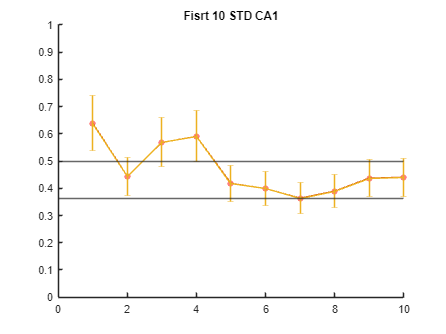

CA1_min = min(STD_CA1_10_N);

err=(STD_CA1_10_N)./sqrt(size(STD_CA1_10_N,2));
err = err./2;

figure
scatter((1:10)',STD_CA1_10_N,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
hold on
plot((1:10)',STD_CA1_10_N)
errorbar((1:10)',STD_CA1_10_N,err(1:10))
yline(CA1_min)
yline(0.5)
title ('Fisrt 10 STD CA1')
ylim([0,1])
xlim([0,10])
cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CA1_STD_10.tif');
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CA1_STD_10.fig']);
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CA1_STD_10.pdf']);

DG_min = min(STD_DG_10_N);

err=(STD_DG_10_N)./sqrt(size(STD_DG_10_N,2))

err =     0.1754    0.0957    0.0992    0.1666    0.1329    0.1453    0.2197    0.1081    0.1382    0.1453


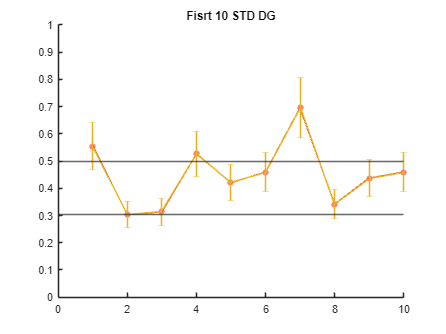

err = err./2;

figure
scatter((1:10)',STD_DG_10_N,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
hold on
plot((1:10)',STD_DG_10_N)
errorbar((1:10)',STD_DG_10_N,err(1:10))
yline(DG_min)
yline(0.5)
title ('Fisrt 10 STD DG')
ylim([0,1])
xlim([0,10])
cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Random_SpkPerTrial_DG_STD_10.tif');
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_DG_STD_10.fig']);
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_DG_STD_10.pdf']);

% 
% figure
% scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./20,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% title ('CA1 Random CSI Sig')
% hold on
% scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./20,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % scatter(AllSTDtrialsRest, STDcountRest,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% hold off
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_STDbefore_DEV.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_STDbefore_DEV.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_STDbefore_DEV.pdf']);

spike_counts = zeros(1,400);
for i = 1:40
spike_counts(1,ODDTrialsComplete(1).ODDtrials(i)) = DEVcount(i,1)./20;
spike_counts(1,STDTrialsComplete(1).STDtrials(i)) = STDcount(i,1)./20;
end

for j = 1:320
spike_counts(1,AllSTDtrialsRest(1).STDtrials(j)) = STDcountRest(j,1)./20;
end

spike_counts_P = zeros(1,400);
for i = 1:40
spike_counts_P(1,ODDTrialsCompleteP(1).ODDtrialsP(i)) = DEVcount_P(i,1)./20;
spike_counts_P(1,STDTrialsComplete_P(1).STDtrials(i)) = STDcount_P(i,1)./20;
end

for j = 1:320
spike_counts_P(1,AllSTDtrialsRest_P(1).STDtrialsP(j)) = STDcountRest_P(j,1)./20;
end


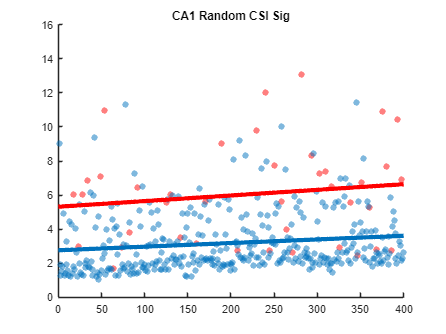

figure
scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./20,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
title ('CA1 Random CSI Sig')
hold on
scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./20,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./20,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
ylim([0,16])
% % scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./max(STDcount),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./max(STDcountRest),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % s=findobj(gca,'Type','Scatter');
% % X = s.XData;
% % Y = s.YData;
% % f1 = polyfit(X,Y,3)
% % y1 = polyval(f1,X);
% % plot(X,y1)
% % scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% % f2 = polyfit(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),3)
% % y2 = polyval(f2,ODDTrialsComplete(1).ODDtrials(1:40));
% % plot(ODDTrialsComplete(1).ODDtrials(1:40),y2)

        % p = polyfit(STDTrialsComplete(1).STDtrials(1:40), STDcount./20, 1);
        % px = [min(STDTrialsComplete(1).STDtrials(1:40)) max(STDTrialsComplete(1).STDtrials(1:40))];
        % py = polyval(p, px);
        % % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
        % 
        % p_r = polyfit(AllSTDtrialsRest(1).STDtrials, STDcountRest./20, 1);
        % px_r = [min(AllSTDtrialsRest(1).STDtrials) max(AllSTDtrialsRest(1).STDtrials)];
        % py_r = polyval(p_r, px_r);
        % % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');
        % 
        % 
        % P= (p+p_r)./2;
        % Px = (px+px_r)./2;
        % Py = polyval(P, Px);
        % plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
        % 
        % 
        % p = polyfit(ODDTrialsComplete(1).ODDtrials(1:40),DEVcount./20, 1);
        % px = [min(ODDTrialsComplete(1).ODDtrials(1:40)) max(ODDTrialsComplete(1).ODDtrials(1:40))];
        % py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

x = 0:400;
y_dev = 5.3157 + (0.0033033) * x;
plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])

y_std = 2.7570 + (0.0021288) * x;
plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Random_SpkPerTrial_STD_DEV.tif');
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_STD_DEV.fig']);
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_STD_DEV.pdf']);

Nor=max(STDcountRest./20);
err=((STDcountRest./20)/Nor)./sqrt(size(STDcountRest,1))

err =     0.0445
    0.0096
    0.0062
    0.0074
    0.0089
    0.0242
    0.0062
    0.0069
    0.0096
    0.0161


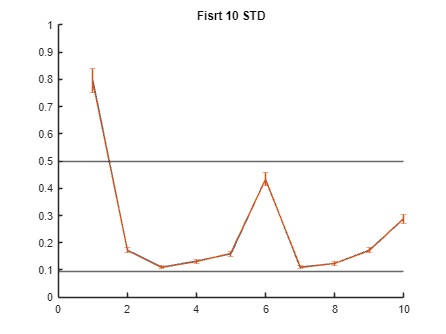

figure
% scatter(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./20)/Nor,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
hold on
plot(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./20)/Nor)
errorbar(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./20)/Nor,err(1:10))
yline((min(STDcountRest./20))/Nor)
yline(0.5)
title ('Fisrt 10 STD')
ylim([0,1])
xlim([0,10])

% figure
% scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./20,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% title ('CA1 Periodic CSI Sig')
% hold on
% scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./20,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% scatter(AllSTDtrialsRest, STDcountRest,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% hold off
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.tif');
% saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.fig']);
% saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.pdf']);

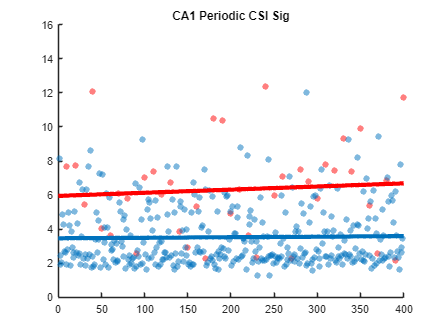

figure
scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./20,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
title ('CA1 Periodic CSI Sig')
hold on
scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./20,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./20,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
ylim([0,16])
        % p = polyfit(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./20, 1);
        % px = [min(STDTrialsComplete_P(1).STDtrials(1:40)) max(STDTrialsComplete_P(1).STDtrials(1:40))];
        % py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
        % 
        % p_r = polyfit(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./20, 1);
        % px_r = [min(AllSTDtrialsRest_P(1).STDtrialsP) max(AllSTDtrialsRest_P(1).STDtrialsP)];
        % py_r = polyval(p_r, px_r);
        % plot(px_r, py_r, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');
        % 
        % P= (p+p_r)./2;
        % Px = (px+px_r)./2;
        % Py = polyval(P, Px);
        % plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
        % 
        % 
        % p = polyfit(ODDTrialsCompleteP(1).ODDtrialsP(1:40),DEVcount_P./20, 1);
        % px = [min(ODDTrialsCompleteP(1).ODDtrialsP(1:40)) max(ODDTrialsCompleteP(1).ODDtrialsP(1:40))];
        % py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

x = 0:400;
y_dev = 5.9515 + (0.0018401) * x;
plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])

y_std = 3.4611 + (0.00031385) * x;
plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

hold off
cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Periodic_SpkPerTrial_STD_DEV.tif');
saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STD_DEV.fig']);
saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STD_DEV.pdf']);

%ODD R vs P
% ODD R referencia
Trials = [ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20];
Group = [ones(40,1); ones(360,1)*2; ones(40,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62876      8.4542    1.3432e-16
    Tiempo             0.0033033    0.0024711      1.3368       0.18168
    Grupo_2              -2.5587       0.6603     -3.8751    0.00011538
    Grupo_3              0.63583       0.8807     0.72196       0.47053
    Grupo_4              -1.8546      0.66033     -2.8086     0.0050986
    Tiempo:Grupo_2    -0.0011744    0.0026237    -0.44763       0.65454
    Tiempo:Grupo_3    -0.0014632    0.0036023    -0.40618       0.68472
    T

anova(modelo, 'summary') % Prueba de significancia de los efectos

ans = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total            3534    799     4.423                         
    Model          633.67      7    90.524      24.72    1.3782e-30
    . Linear       623.24      4    155.81     42.548    2.3709e-32
    . Nonlinear    10.425      3    3.4749    0.94891        0.4164
    Residual       2900.3    792     3.662                         


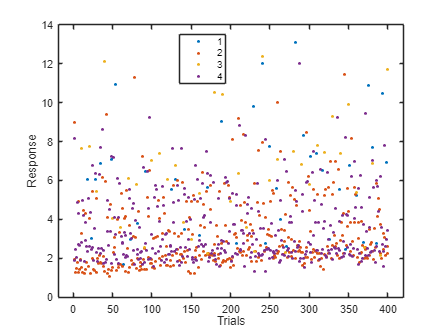


%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62876      8.4542    1.3432e-16
    Tiempo             0.0033033    0.0024711      1.3368       0.18168
    Grupo_2              -2.5587       0.6603     -3.8751    0.00011538
    Grupo_3              0.63583       0.8807     0.72196       0.47053
    Grupo_4              -1.8546      0.66033     -2.8086     0.0050986
    Tiempo:Grupo_2    -0.0011744    0.0026237    -0.44763       0.65454
    Tiempo:Grupo_3    -0.0014632    0.0036023    -0.40618       0.68472
    

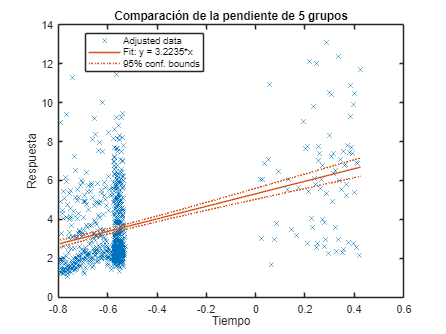

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% STD R referencia
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsComplete(1).ODDtrials(1:40);ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [STDcount./20;STDcountRest./20;DEVcount./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20];
Group = [ones(360,1)*2; ones(40,1); ones(40,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62876      8.4542    1.3432e-16
    Tiempo             0.0033033    0.0024711      1.3368       0.18168
    Grupo_2              -2.5587       0.6603     -3.8751    0.00011538
    Grupo_3              0.63583       0.8807     0.72196       0.47053
    Grupo_4              -1.8546      0.66033     -2.8086     0.0050986
    Tiempo:Grupo_2    -0.0011744    0.0026237    -0.44763       0.65454
    Tiempo:Grupo_3    -0.0014632    0.0036023    -0.40618       0.68472
    T

anova(modelo, 'summary') % Prueba de significancia de los efectos

ans = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total            3534    799     4.423                         
    Model          633.67      7    90.524      24.72    1.3782e-30
    . Linear       623.24      4    155.81     42.548    2.3709e-32
    . Nonlinear    10.425      3    3.4749    0.94891        0.4164
    Residual       2900.3    792     3.662                         



%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62876      8.4542    1.3432e-16
    Tiempo             0.0033033    0.0024711      1.3368       0.18168
    Grupo_2              -2.5587       0.6603     -3.8751    0.00011538
    Grupo_3              0.63583       0.8807     0.72196       0.47053
    Grupo_4              -1.8546      0.66033     -2.8086     0.0050986
    Tiempo:Grupo_2    -0.0011744    0.0026237    -0.44763       0.65454
    Tiempo:Grupo_3    -0.0014632    0.0036023    -0.40618       0.68472
    

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% ODD P referencia
Trials = [ODDTrialsCompleteP(1).ODDtrialsP(1:40);ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [DEVcount_P./20;DEVcount./20;STDcount./20;STDcountRest./20;STDcount_P./20;STDcountRest_P./20];
Group = [ ones(40,1)*1; ones(40,1)*2; ones(360,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

%% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.9515      0.61667      9.6511    6.5264e-21
    Tiempo             0.0018401    0.0026212       0.702       0.48289
    Grupo_2             -0.63583       0.8807    -0.72196       0.47053
    Grupo_3              -3.1946      0.64879     -4.9239    1.0329e-06
    Grupo_4              -2.4904      0.64883     -3.8383    0.00013374
    Tiempo:Grupo_2     0.0014632    0.0036023     0.40618       0.68472
    Tiempo:Grupo_3    0.00028878    0.0027655     0.10442       0.91686
    T


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total            3534    799     4.423                         
    Model          633.67      7    90.524      24.72    1.3782e-30
    . Linear       623.24      4    155.81     42.548    2.3709e-32
    . Nonlinear    10.425      3    3.4749    0.94891        0.4164
    Residual       2900.3    792     3.662                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m

correctedPValues =        NaN
    0.0000
    0.0000
    2.0820
       NaN



% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.6106e-20              1.9315      
            1.8821              2.7389      
        4.1315e-06              3.6674      
        0.00053497              2.3233      


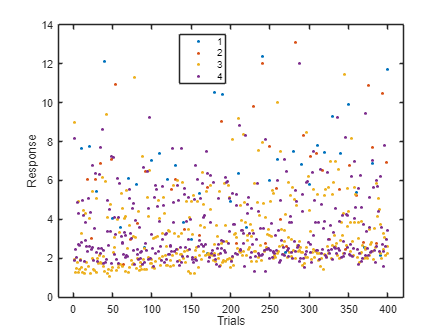

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.9515      0.61667      9.6511    6.5264e-21
    Tiempo             0.0018401    0.0026212       0.702       0.48289
    Grupo_2             -0.63583       0.8807    -0.72196       0.47053
    Grupo_3              -3.1946      0.64879     -4.9239    1.0329e-06
    Grupo_4              -2.4904      0.64883     -3.8383    0.00013374
    Tiempo:Grupo_2     0.0014632    0.0036023     0.40618       0.68472
    Tiempo:Grupo_3    0.00028878    0.0027655     0.10442       0.91686
    

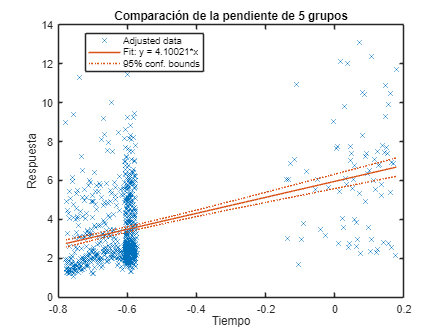

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% STD P referencia
Trials = [STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40)];
Response = [STDcount_P./20;STDcountRest_P./20;DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20];
Group = [ ones(360,1)*4;ones(40,1); ones(360,1)*2; ones(40,1)*3];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

%% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62876      8.4542    1.3432e-16
    Tiempo             0.0033033    0.0024711      1.3368       0.18168
    Grupo_2              -2.5587       0.6603     -3.8751    0.00011538
    Grupo_3              0.63583       0.8807     0.72196       0.47053
    Grupo_4              -1.8546      0.66033     -2.8086     0.0050986
    Tiempo:Grupo_2    -0.0011744    0.0026237    -0.44763       0.65454
    Tiempo:Grupo_3    -0.0014632    0.0036023    -0.40618       0.68472
    T


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total            3534    799     4.423                         
    Model          633.67      7    90.524      24.72    1.3782e-30
    . Linear       623.24      4    155.81     42.548    2.3709e-32
    . Nonlinear    10.425      3    3.4749    0.94891        0.4164
    Residual       2900.3    792     3.662                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        5.3729e-16             0.72674      
        0.00046152              2.6182      
            1.8821              2.7389      
          0.020394              1.0175      


%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62876      8.4542    1.3432e-16
    Tiempo             0.0033033    0.0024711      1.3368       0.18168
    Grupo_2              -2.5587       0.6603     -3.8751    0.00011538
    Grupo_3              0.63583       0.8807     0.72196       0.47053
    Grupo_4              -1.8546      0.66033     -2.8086     0.0050986
    Tiempo:Grupo_2    -0.0011744    0.0026237    -0.44763       0.65454
    Tiempo:Grupo_3    -0.0014632    0.0036023    -0.40618       0.68472
    

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

spike_counts_MSC = zeros(1,400);
for i = 1:40
spike_counts_MSC(1,CTRMSTrialsComplete_F1(1).CTRMStrials(i)) = MScount_F1(i,1)./20;
spike_counts_MSC(1,CTRMSTrialsComplete_F2(1).CTRMStrials(i)) = MScount_F2(i,1)./20;
end

for j = 1:320
spike_counts_MSC(1,MStrialsRest(1).MStrials(j)) = MScount_rest(j,1)./20;
end

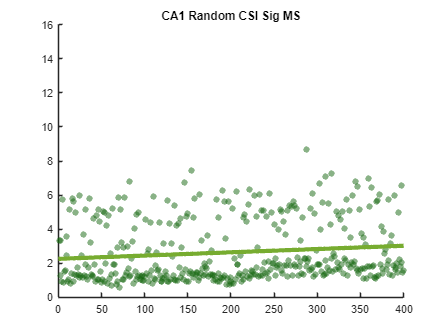

%MS
figure
scatter(CTRMSTrialsComplete_F1(1).CTRMStrials, MScount_F1./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('CA1 Random CSI Sig MS')
hold on
scatter(CTRMSTrialsComplete_F2(1).CTRMStrials, MScount_F2./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(MStrialsRest(1).MStrials, MScount_rest./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
ylim([0,16])

        % p1 = polyfit(CTRMSTrialsComplete_F1(1).CTRMStrials,MScount_F1./20, 1);
        % px1 = [min(CTRMSTrialsComplete_F1(1).CTRMStrials) max(CTRMSTrialsComplete_F1(1).CTRMStrials)];
        % py = polyval(p1, px1);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);
        % 
        %  p2 = polyfit(CTRMSTrialsComplete_F2(1).CTRMStrials,MScount_F2./20, 1);
        % px2 = [min(CTRMSTrialsComplete_F2(1).CTRMStrials) max(CTRMSTrialsComplete_F2(1).CTRMStrials)];
        % py = polyval(p2, px2);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');
        % 
        %  pT = polyfit(MStrialsRest(1).MStrials,MScount_rest./20, 1);
        % pxT = [min(MStrialsRest(1).MStrials) max(MStrialsRest(1).MStrials)];
        % py = polyval(pT, pxT);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');
        % 
        % P= (p1+p2+pT)./3;
        % Px = (px1+px2+pxT)./3;
        % py = polyval(P, Px);
        % plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

x = 0:400;
y_msc = 2.2546 + (0.0019218) * x;
plot(x,y_msc, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])

cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Random_SpkPerTrial_MS.tif');
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_MS.fig']);
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_MS.pdf']);

spike_counts_CASCASC = zeros(1,400);
for i = 1:40
spike_counts_CASCASC(1,CTR_ASC_F1TrialsComplete(1).CTRtrials(i)) = CASCasccount_F1(i,1)./20;
spike_counts_CASCASC(1,CTR_ASC_F2TrialsComplete(1).CTRtrials(i)) = CASCasccount_F2(i,1)./20;
end

for j = 1:320
spike_counts_CASCASC(1,CASCasctrialsRest(1).CASCasctrials(j)) = CASCasccount_rest(j,1)./20;
end

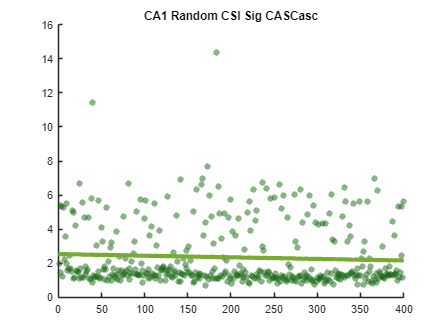

%CASCASC
figure
scatter(CTR_ASC_F1TrialsComplete(1).CTRtrials, CASCasccount_F1./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('CA1 Random CSI Sig CASCasc')
hold on
scatter(CTR_ASC_F2TrialsComplete(1).CTRtrials, CASCasccount_F2./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(CASCasctrialsRest(1).CASCasctrials, CASCasccount_rest./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCASC.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.pdf']);
ylim([0,16])

        % p1 = polyfit(CTR_ASC_F1TrialsComplete(1).CTRtrials,CASCasccount_F1./20, 1);
        % px1 = [min(CTR_ASC_F1TrialsComplete(1).CTRtrials) max(CTR_ASC_F1TrialsComplete(1).CTRtrials)];
        % py = polyval(p1, px1);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);
        % 
        %  p2 = polyfit(CTR_ASC_F2TrialsComplete(1).CTRtrials,CASCasccount_F2./20, 1);
        % px2 = [min(CTR_ASC_F2TrialsComplete(1).CTRtrials) max(CTR_ASC_F2TrialsComplete(1).CTRtrials)];
        % py = polyval(p2, px2);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');
        % 
        %  pT = polyfit(CASCasctrialsRest(1).CASCasctrials,CASCasccount_rest./20, 1);
        % pxT = [min(CASCasctrialsRest(1).CASCasctrials) max(CASCasctrialsRest(1).CASCasctrials)];
        % py = polyval(pT, pxT);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');
        % 
        % P= (p1+p2+pT)./3;
        % Px = (px1+px2+pxT)./3;
        % py = polyval(P, Px);
        % plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

x = 0:400;
y_cascasc = 2.5347 + (-0.00094849) * x;
plot(x,y_cascasc, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])

cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCasc.tif');
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCasc.fig']);
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCasc.pdf']);

spike_counts_CASCDES = zeros(1,400);
for i = 1:40
spike_counts_CASCDES(1,CTR_DESC_F1TrialsComplete(1).CTRtrials(i)) = CASCdescount_F1(i,1)./20;
spike_counts_CASCDES(1,CTR_DESC_F2TrialsComplete(1).CTRtrials(i)) = CASCdescount_F2(i,1)./20;
end

for j = 1:320
spike_counts_CASCDES(1,CASCdestrialsRest(1).CASCdes(j)) = CASCdescount_rest(j,1)./20;
end

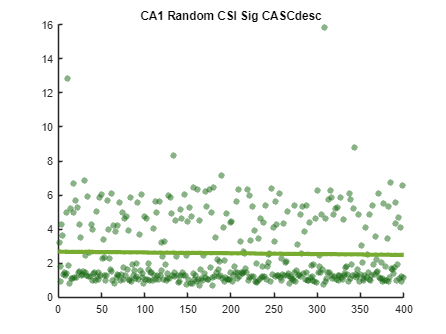

%CASCdesc
figure
scatter(CTR_DESC_F1TrialsComplete(1).CTRtrials, CASCdescount_F1./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('CA1 Random CSI Sig CASCdesc')
hold on
scatter(CTR_DESC_F2TrialsComplete(1).CTRtrials, CASCdescount_F2./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(CASCdestrialsRest(1).CASCdes, CASCdescount_rest./20,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCASC.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.pdf']);
ylim([0,16])
        % p1 = polyfit(CTR_DESC_F1TrialsComplete(1).CTRtrials,CASCdescount_F1./20, 1);
        % px1 = [min(CTR_DESC_F1TrialsComplete(1).CTRtrials) max(CTR_DESC_F1TrialsComplete(1).CTRtrials)];
        % py = polyval(p1, px1);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);
        % 
        %  p2 = polyfit(CTR_DESC_F2TrialsComplete(1).CTRtrials,CASCdescount_F2./20, 1);
        % px2 = [min(CTR_DESC_F2TrialsComplete(1).CTRtrials) max(CTR_DESC_F2TrialsComplete(1).CTRtrials)];
        % py = polyval(p2, px2);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');
        % 
        %  pT = polyfit(CASCdestrialsRest(1).CASCdes,CASCdescount_rest./20, 1);
        % pxT = [min(CASCdestrialsRest(1).CASCdes) max(CASCdestrialsRest(1).CASCdes)];
        % py = polyval(pT, pxT);
        % % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');
        % 
        % P= (p1+p2+pT)./3;
        % Px = (px1+px2+pxT)./3;
        % py = polyval(P, Px);
        % plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

x = 0:400;
y_cascdes = 2.6757 + (-0.0004692) * x;
plot(x,y_cascdes, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])

cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCdes.tif');
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCdes.fig']);
saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCdes.pdf']);

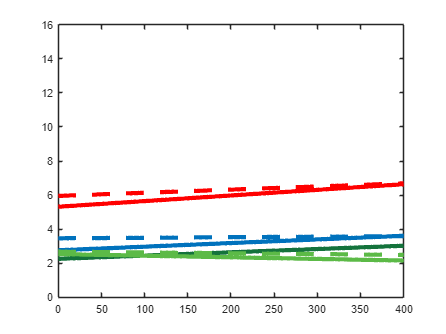

figure
x = 0:400;
y_dev = 5.3157 + (0.0033033) * x;
plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])
ylim([0,16])
hold on

y_std = 2.7570 + (0.0021288) * x;
plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

y_dev_p = 5.9515 + (0.0018401) * x;
plot(x,y_dev_p, 'LineWidth', 4,'Color',[1 0 0],'linestyle','--')

y_std_p = 3.4611 + (0.00031385) * x;
plot(x,y_std_p, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--')

y_msc = 2.2546 + (0.0019218) * x;
plot(x,y_msc, 'LineWidth', 4,'Color','#14733C')

y_cascasc = 2.5347 + (-0.00094849) * x;
plot(x,y_cascasc, 'LineWidth', 4,'Color','#5CBA47')

y_cascdes = 2.6757 + (-0.0004692) * x;
plot(x,y_cascdes, 'LineWidth', 4,'Color','#5CBA47','linestyle','--')

cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
saveas(gcf,'HIP_Fits.tif');
saveas(gcf,['HIP_Fits.fig']);
saveas(gcf,['HIP_Fits.pdf']);

%ODD vs the rest
% DEV R; STD R; DEV P; STD P; MS; CASC ASC; CASC DESC
Trials = [ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(40,1); ones(360,1)*2; ones(40,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62466      8.5098    3.3783e-17
    Tiempo             0.0033033    0.0024549      1.3456        0.1786
    Grupo_2              -2.5587      0.65598     -3.9006    9.9136e-05
    Grupo_3              0.63583      0.87494     0.72671       0.46749
    Grupo_4              -1.8546      0.65602      -2.827      0.004745
    Grupo_5              -3.0611      0.65305     -4.6875     2.954e-06
    Grupo_6               -2.781      0.65305     -4.2585    2.1537e-05
    G


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(9,1);
m_pvalues(3,1) = p_values(10,1);
m_pvalues(4,1) = p_values(11,1);
m_pvalues(5,1) = p_values(12,1);
m_pvalues(6,1) = p_values(13,1);
m_pvalues(7,1) = p_values(14,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);
y_pvalues(6,1) = p_values(7,1);
y_pvalues(7,1) = p_values(8,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.3648e-16              1.2502      
        0.00069395              4.5664      
            3.2724              4.7788      
          0.033215              1.7575      
        2.0678e-05               4.156      
        0.00015076             0.70516      
        0.00038417               1.017      


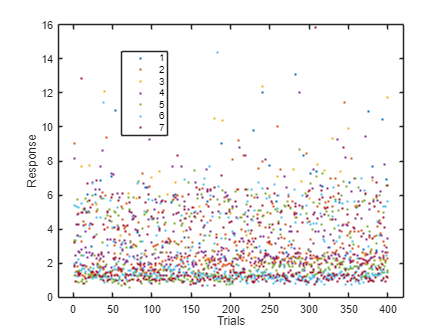

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.3157      0.62466      8.5098    3.3783e-17
    Tiempo             0.0033033    0.0024549      1.3456        0.1786
    Grupo_2              -2.5587      0.65598     -3.9006    9.9136e-05
    Grupo_3              0.63583      0.87494     0.72671       0.46749
    Grupo_4              -1.8546      0.65602      -2.827      0.004745
    Grupo_5              -3.0611      0.65305     -4.6875     2.954e-06
    Grupo_6               -2.781      0.65305     -4.2585    2.1537e-05
    

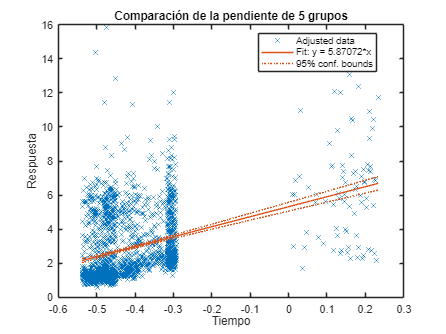

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD R vs the rest
% STD R; DEV R; DEV P; STD P; MS; CASC ASC; CASC DESC
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsComplete(1).ODDtrials(1:40);ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount./20;STDcountRest./20;DEVcount./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ ones(360,1)*1; ones(40,1)*2; ones(40,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)             2.757      0.20029      13.765    3.0382e-41
    Tiempo              0.0021288    0.0008759      2.4304      0.015168
    Grupo_2                2.5587      0.65598      3.9006    9.9136e-05
    Grupo_3                3.1946      0.64455      4.9563    7.7955e-07
    Grupo_4               0.70414      0.28333      2.4852      0.013029
    Grupo_5              -0.50242       0.2764     -1.8177      0.069254
    Grupo_6               -0.2223       0.2764    -0.80429       0.42132
    


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.1267e-40             0.10618      
        0.00069395              2.9493      
        5.4568e-06              5.3812      
          0.091205              4.5664      
           0.48478              6.4141      
        0.00015076             0.70516      
        0.00038417               1.017      


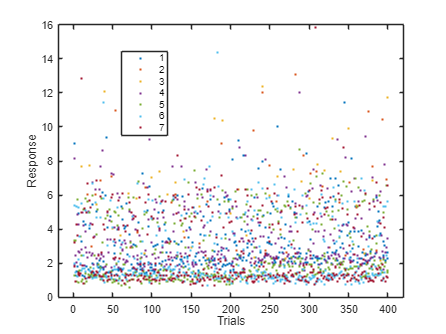

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)             2.757      0.20029      13.765    3.0382e-41
    Tiempo              0.0021288    0.0008759      2.4304      0.015168
    Grupo_2                2.5587      0.65598      3.9006    9.9136e-05
    Grupo_3                3.1946      0.64455      4.9563    7.7955e-07
    Grupo_4               0.70414      0.28333      2.4852      0.013029
    Grupo_5              -0.50242       0.2764     -1.8177      0.069254
    Grupo_6               -0.2223       0.2764    -0.80429       0.42132

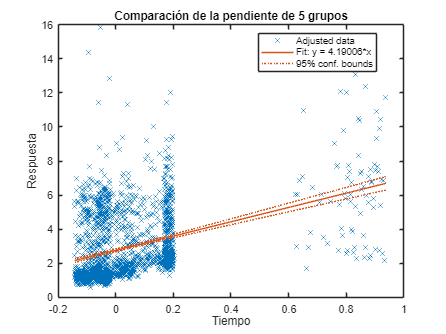

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD P vs the rest
% DEV P; DEV R; STD R; STD P; MS; CASC ASC; CASC DESC
Trials = [ODDTrialsCompleteP(1).ODDtrialsP(1:40);ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [DEVcount_P./20;DEVcount./20;STDcount./20;STDcountRest./20;STDcount_P./20;STDcountRest_P./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(40,1)*1; ones(40,1)*2; ones(360,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.9515      0.61264      9.7145    7.9313e-22
    Tiempo             0.0018401     0.002604     0.70662       0.47989
    Grupo_2             -0.63583      0.87494    -0.72671       0.46749
    Grupo_3              -3.1946      0.64455     -4.9563    7.7955e-07
    Grupo_4              -2.4904      0.64459     -3.8636    0.00011532
    Grupo_5               -3.697      0.64157     -5.7624    9.5901e-09
    Grupo_6              -3.4169      0.64157     -5.3258    1.1189e-07
    G


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        5.5519e-21                3.3592    
            3.2724            7.8323e-07    
        5.4568e-06            2.5235e-06    
        0.00080722                4.7788    
         6.713e-08                6.4141    
        0.00015076               0.70516    
        0.00038417                 1.017    


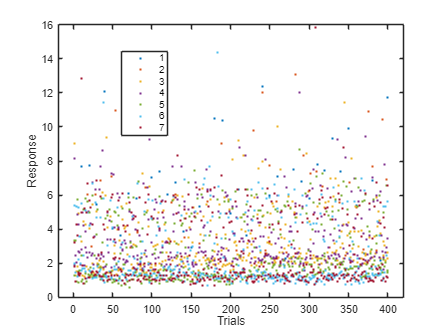

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.9515      0.61264      9.7145    7.9313e-22
    Tiempo             0.0018401     0.002604     0.70662       0.47989
    Grupo_2             -0.63583      0.87494    -0.72671       0.46749
    Grupo_3              -3.1946      0.64455     -4.9563    7.7955e-07
    Grupo_4              -2.4904      0.64459     -3.8636    0.00011532
    Grupo_5               -3.697      0.64157     -5.7624    9.5901e-09
    Grupo_6              -3.4169      0.64157     -5.3258    1.1189e-07
    

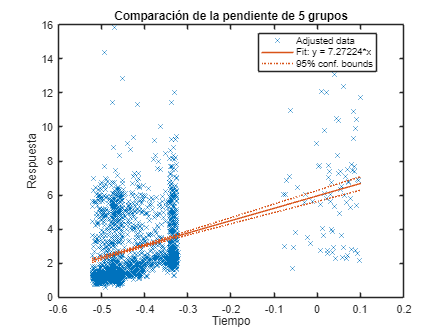

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD P vs the rest
% STD P; DEV R; STD R; DEV P; MS; CASC ASC; CASC DESC
Trials = [STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount_P./20;STDcountRest_P./20;DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(360,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)            3.4611      0.20041      17.271    2.2408e-62
    Tiempo             0.00031385    0.0008678     0.36167       0.71764
    Grupo_2                1.8546      0.65602       2.827      0.004745
    Grupo_3              -0.70414      0.28333     -2.4852      0.013029
    Grupo_4                2.4904      0.64459      3.8636    0.00011532
    Grupo_5               -1.2066      0.27648      -4.364    1.3426e-05
    Grupo_6              -0.92645      0.27648     -3.3509    0.00082071
    


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.5685e-61               5.0235     
          0.033215             0.005745     
          0.091205             0.031824     
        0.00080722               1.7575     
        9.3984e-05              0.98824     
        0.00015076              0.70516     
        0.00038417                1.017     


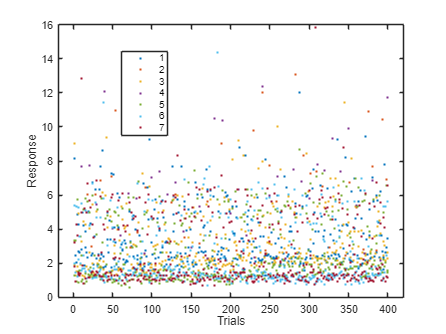

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)            3.4611      0.20041      17.271    2.2408e-62
    Tiempo             0.00031385    0.0008678     0.36167       0.71764
    Grupo_2                1.8546      0.65602       2.827      0.004745
    Grupo_3              -0.70414      0.28333     -2.4852      0.013029
    Grupo_4                2.4904      0.64459      3.8636    0.00011532
    Grupo_5               -1.2066      0.27648      -4.364    1.3426e-05
    Grupo_6              -0.92645      0.27648     -3.3509    0.00082071

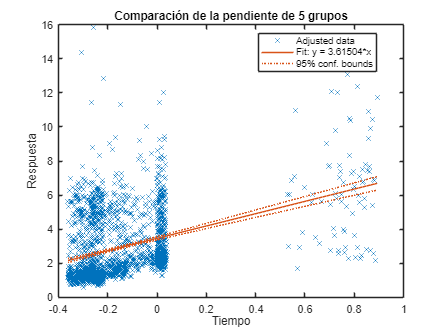

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%MS vs the rest
% MS; DEV R; STD R; DEV P; STD P; CASC ASC; CASC DESC
Trials = [CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [MScount_F1./20;MScount_F2./20; MScount_rest./20;DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(400,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat        pValue  
                      ___________    __________    ________    __________

    (Intercept)            2.2546       0.19047      11.837    2.7608e-31
    Tiempo              0.0019218    0.00082322      2.3345       0.01967
    Grupo_2                3.0611       0.65305      4.6875     2.954e-06
    Grupo_3               0.50242        0.2764      1.8177      0.069254
    Grupo_4                 3.697       0.64157      5.7624    9.5901e-09
    Grupo_5                1.2066       0.27648       4.364    1.3426e-05
    Grupo_6               0.28011       0.26937      1.0399       0.2


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.9325e-30             0.13769      
        2.0678e-05              2.0896      
           0.48478             0.82674      
         6.713e-08               4.156      
        9.3984e-05              6.0428      
        0.00015076             0.70516      
        0.00038417               1.017      


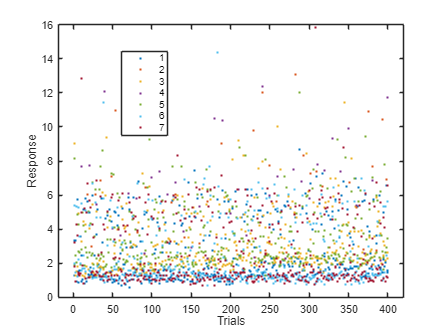

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat        pValue  
                      ___________    __________    ________    __________

    (Intercept)            2.2546       0.19047      11.837    2.7608e-31
    Tiempo              0.0019218    0.00082322      2.3345       0.01967
    Grupo_2                3.0611       0.65305      4.6875     2.954e-06
    Grupo_3               0.50242        0.2764      1.8177      0.069254
    Grupo_4                 3.697       0.64157      5.7624    9.5901e-09
    Grupo_5                1.2066       0.27648       4.364    1.3426e-05
    Grupo_6               0.28011       0.26937      1.0399     

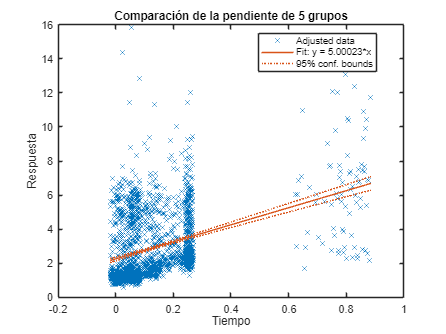

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%CASC ASC vs the rest
% CASC ASC; DEV R; STD R; DEV P; STD P; MS; CASC DESC
Trials = [CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(400,1)*1;ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat       pValue  
                      ___________    __________    _______    __________

    (Intercept)            2.5347       0.19047     13.307    9.0877e-39
    Tiempo            -0.00094849    0.00082322    -1.1522       0.24939
    Grupo_2                 2.781       0.65305     4.2585    2.1537e-05
    Grupo_3                0.2223        0.2764    0.80429       0.42132
    Grupo_4                3.4169       0.64157     5.3258    1.1189e-07
    Grupo_5               0.92645       0.27648     3.3509    0.00082071
    Grupo_6              -0.28011       0.26937    -1.0399       0.29851
    


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        6.3614e-38               1.7457     
        0.00015076               2.0896     
            2.9493               4.2045     
        7.8323e-07              0.70516     
          0.005745             0.073764     
        0.00015076              0.70516     
        0.00038417                1.017     


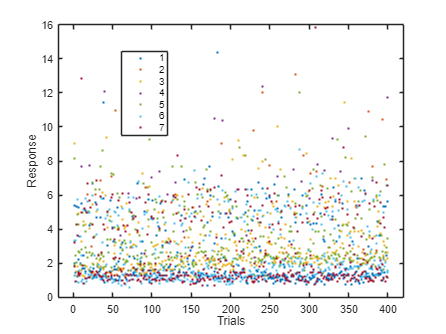

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat       pValue  
                      ___________    __________    _______    __________

    (Intercept)            2.5347       0.19047     13.307    9.0877e-39
    Tiempo            -0.00094849    0.00082322    -1.1522       0.24939
    Grupo_2                 2.781       0.65305     4.2585    2.1537e-05
    Grupo_3                0.2223        0.2764    0.80429       0.42132
    Grupo_4                3.4169       0.64157     5.3258    1.1189e-07
    Grupo_5               0.92645       0.27648     3.3509    0.00082071
    Grupo_6              -0.28011       0.26937    -1.0399       0.29851

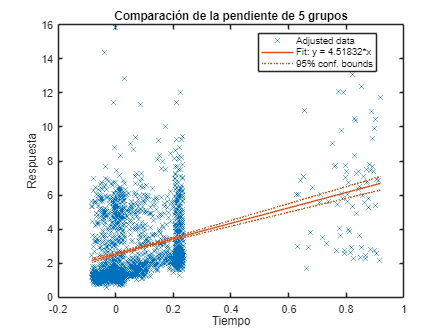

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%CASC DESC vs the rest
% CASC DESC; DEV R; STD R; DEV P; STD P; MS; CASC ASC
Trials = [CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials];
    Response = [CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20;DEVcount./20;STDcount./20;STDcountRest./20;DEVcount_P./20;STDcount_P./20;STDcountRest_P./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20];
Group = [ones(400,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      __________    __________    ________    __________

    (Intercept)           2.6757       0.19047      14.048    8.2776e-43
    Tiempo            -0.0004692    0.00082322    -0.56996       0.56877
    Grupo_2                 2.64       0.65305      4.0426    5.4882e-05
    Grupo_3             0.081276        0.2764     0.29406       0.76874
    Grupo_4               3.2758       0.64157       5.106     3.605e-07
    Grupo_5              0.78542       0.27648      2.8408     0.0045462
    Grupo_6             -0.42114       0.26937     -1.5635       0.11811
    


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          8451.6    1999    4.2279                        
    Model          1273.7      13    97.974    27.107    1.2098e-61
    . Linear       1228.9       7    175.56    48.573    5.4785e-64
    . Nonlinear    44.755       6    7.4592    2.0638      0.054466
    Residual         7178    1986    3.6143                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue    m Bonfe_Cor_pValue
    __________    __________________

                             NaN    
    1.2098e-61        6.0489e-61    
    5.4785e-64        2.7392e-63    
      0.054466           0.27233    
                             NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        5.7944e-42              3.9814      
        0.00038417             0.82674      
            5.3812              4.2045      
        2.5235e-06               1.017      
          0.031824             0.21551      
        0.00015076             0.70516      
        0.00038417               1.017      


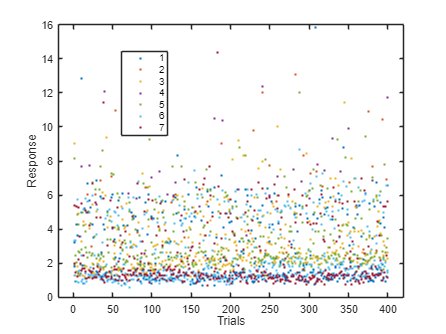

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      __________    __________    ________    __________

    (Intercept)           2.6757       0.19047      14.048    8.2776e-43
    Tiempo            -0.0004692    0.00082322    -0.56996       0.56877
    Grupo_2                 2.64       0.65305      4.0426    5.4882e-05
    Grupo_3             0.081276        0.2764     0.29406       0.76874
    Grupo_4               3.2758       0.64157       5.106     3.605e-07
    Grupo_5              0.78542       0.27648      2.8408     0.0045462
    Grupo_6             -0.42114       0.26937     -1.5635       0.11811

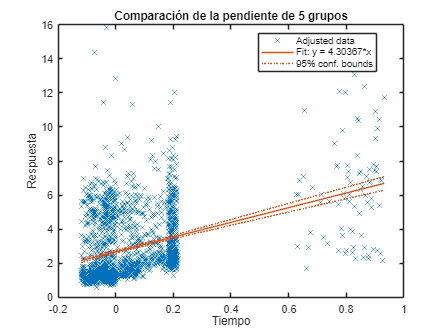

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD vs CTR
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount./20;STDcountRest./20;MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(360,1)*2; ones(400,1)*3; ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat        pValue  
                      ___________    __________    ________    __________

    (Intercept)             2.757       0.19647      14.033    3.3232e-42
    Tiempo              0.0021288    0.00085919      2.4777      0.013329
    Grupo_3              -0.50242       0.27112     -1.8531      0.064059
    Grupo_4               -0.2223       0.27112    -0.81993       0.41238
    Grupo_5             -0.081276       0.27112    -0.29978       0.76439
    Tiempo:Grupo_3    -0.00020706     0.0011791    -0.17561       0.86062
    Tiempo:Grupo_4     -0.0030773     0.0011791     -2.6099     0.009


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue  
                   ______    ____    ______    ______    __________

    Total          5583.4    1559    3.5814                        
    Model          185.94       7    26.563    7.6381    4.3442e-09
    . Linear       146.73       4    36.683    10.548    1.9659e-08
    . Nonlinear     39.21       3     13.07    3.7582      0.010508
    Residual       5397.4    1552    3.4777                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.3293e-41             0.053314     
           0.25624               3.4425     
            1.6495             0.036578     
            3.0576              0.11085     


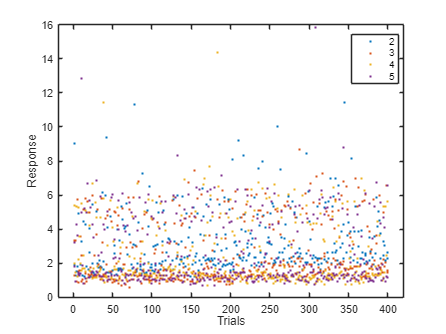

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

%CTR MS vs CASC
Trials = [CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [MScount_F1./20;MScount_F2./20; MScount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(400,1)*3; ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           2.2546      0.18963     11.889    6.9125e-31
    Tiempo             0.0019218    0.0008196     2.3448      0.019203
    Grupo_4              0.28011      0.26818     1.0445       0.29647
    Grupo_5              0.42114      0.26818     1.5703        0.1166
    Tiempo:Grupo_4    -0.0028703    0.0011591    -2.4763      0.013413
    Tiempo:Grupo_5     -0.002391    0.0011591    -2.0628      0.039348


Number of observations: 1200, Error degrees of freedom: 1194
Root Mean Squared Error: 1.89
R-squared: 0.0105



clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(5,1);
m_pvalues(3,1) = p_values(6,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F        pValue 
                   ______    ____    ______    ______    ________

    Total          4322.9    1199    3.6054                      
    Model          45.251       5    9.0503    2.5261    0.027647
    . Linear       20.034       3     6.678     1.864     0.13386
    . Nonlinear    25.217       2    12.609    3.5194    0.029925
    Residual       4277.7    1194    3.5826                      


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 3×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.0737e-30             0.057608     
           0.88942             0.040239     
            0.3498              0.11805     


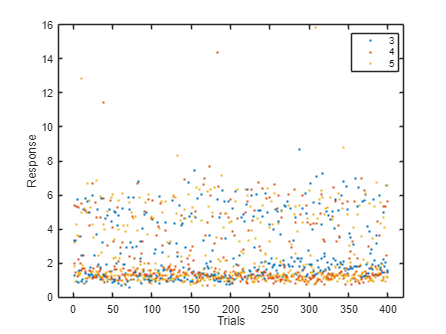

%%%%%%%%%%%%%%%%%%%%%%%
figure;
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

% ASC vs DESC
Trials = [CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20;CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20];
Group = [ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat       pValue  
                      ___________    __________    _______    __________

    (Intercept)            2.5347       0.19498     12.999    3.5627e-35
    Tiempo            -0.00094849    0.00084273    -1.1255       0.26072
    Grupo_5               0.14103       0.27575    0.51143       0.60919
    Tiempo:Grupo_5      0.0004793     0.0011918    0.40216       0.68767


Number of observations: 800, Error degrees of freedom: 796
Root Mean Squared Error: 1.95
R-squared: 0.00568,  Adjusted R-Squared: 0.00193
F-statistic vs. constant model: 1.52, p-value = 0.209



% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m = length(p_values); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = p_values * m; 
% Display results
clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(4,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                    SumSq     DF     MeanSq        F       pValue 
                   _______    ___    _______    _______    _______

    Total           3032.2    799      3.795                      
    Model           17.218      3     5.7393     1.5153    0.20913
    . Linear        16.605      2     8.3026      2.192    0.11237
    . Nonlinear    0.61259      1    0.61259    0.16173    0.68767
    Residual          3015    796     3.7877                      


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 2×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        7.1254e-35             0.52143      
            1.2184              1.3753      


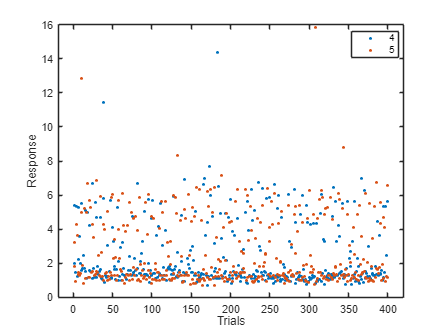

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

% DESC vs ASC 
Trials = [CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials];
Response = [CASCdescount_F1./20;CASCdescount_F2./20;CASCdescount_rest./20;CASCasccount_F1./20;CASCasccount_F2./20;CASCasccount_rest./20];
Group = [ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate          SE         tStat       pValue  
                      ___________    __________    _______    __________

    (Intercept)            2.5347       0.19498     12.999    3.5627e-35
    Tiempo            -0.00094849    0.00084273    -1.1255       0.26072
    Grupo_5               0.14103       0.27575    0.51143       0.60919
    Tiempo:Grupo_5      0.0004793     0.0011918    0.40216       0.68767


Number of observations: 800, Error degrees of freedom: 796
Root Mean Squared Error: 1.95
R-squared: 0.00568,  Adjusted R-Squared: 0.00193
F-statistic vs. constant model: 1.52, p-value = 0.209



% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m = length(p_values); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = p_values * m; 
% Display results
clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(4,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                    SumSq     DF     MeanSq        F       pValue 
                   _______    ___    _______    _______    _______

    Total           3032.2    799      3.795                      
    Model           17.218      3     5.7393     1.5153    0.20913
    . Linear        16.605      2     8.3026      2.192    0.11237
    . Nonlinear    0.61259      1    0.61259    0.16173    0.68767
    Residual          3015    796     3.7877                      


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 2×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        7.1254e-35             0.52143      
            1.2184              1.3753      


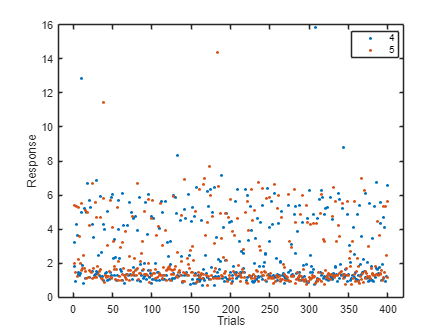

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

MScount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,13));
        for i = 1:size(MStimes_F1{1,1},1)
            if MStimes_F1{1,1}(i) >= 200 && MStimes_F1{1,1}(i) <= 650
                MScount_F1V(k,j) = MScount_F1V(k,j) + 1;
            end
        end
    end
end

MScount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,12));
        for i = 1:size(MStimes_F2{1,1},1)
            if MStimes_F2{1,1}(i) >= 200 && MStimes_F2{1,1}(i) <= 650
                MScount_F2V(k,j) = MScount_F2V(k,j) + 1;
            end
        end
    end
end

MScount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        MStimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,11));
        for i = 1:size(MStimesRest{1,1},1)
            if MStimesRest{1,1}(i) >= 200 && MStimesRest{1,1}(i) <= 650
                MScount_restV(k,j) = MScount_restV(k,j) + 1;
            end
        end
    end
end

CASCasccount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,15));
        for i = 1:size(CASCasctimes_F1{1,1},1)
            if CASCasctimes_F1{1,1}(i) >= 200 && CASCasctimes_F1{1,1}(i) <= 650
                CASCasccount_F1V(k,j) = CASCasccount_F1V(k,j) + 1;
            end
        end
    end
end

CASCasccount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,16));
        for i = 1:size(CASCasctimes_F2{1,1},1)
            if CASCasctimes_F2{1,1}(i) >= 200 && CASCasctimes_F2{1,1}(i) <= 650
                CASCasccount_F2V(k,j) = CASCasccount_F2V(k,j) + 1;
            end
        end
    end
end

CASCasccount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCasctimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,14));
        for i = 1:size(CASCasctimesRest{1,1},1)
            if CASCasctimesRest{1,1}(i) >= 200 && CASCasctimesRest{1,1}(i) <= 650
                CASCasccount_restV(k,j) = CASCasccount_restV(k,j) + 1;
            end
        end
    end
end

CASCdescount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,19));
        for i = 1:size(CASCdestimes_F1{1,1},1)
            if CASCdestimes_F1{1,1}(i) >= 200 && CASCdestimes_F1{1,1}(i) <= 650
                CASCdescount_F1V(k,j) = CASCdescount_F1V(k,j) + 1;
            end
        end
    end
end

CASCdescount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,18));
        for i = 1:size(CASCdestimes_F2{1,1},1)
            if CASCdestimes_F2{1,1}(i) >= 200 && CASCdestimes_F2{1,1}(i) <= 650
                CASCdescount_F2V(k,j) = CASCdescount_F2V(k,j) + 1;
            end
        end
    end
end

CASCdescount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCdestimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,17));
        for i = 1:size(CASCdestimesRest{1,1},1)
            if CASCdestimesRest{1,1}(i) >= 200 && CASCdestimesRest{1,1}(i) <= 650
                CASCdescount_restV(k,j) = CASCdescount_restV(k,j) + 1;
            end
        end
    end
end

sequence = zeros(1,400);
% ODDTrialIndex = ODDTrialIndex-20;
for i = 1:40
    for j = 1:400
        if ismember(j,ODDTrialIndex(i,1))
            sequence(1,j) = 1;
        end
    end
end


sequence_P = zeros(1,400);
% ODDTrialIndexP = ODDTrialIndexP-440;
for i = 1:40
    for j = 1:400
        if ismember(j,ODDTrialIndexP(i,1))
            sequence_P(1,j) = 1;
        end
    end
end



    DEVx = ODDTrialsComplete(1).ODDtrials(1:40);
    DEVy = DEVcount./20;

    STDTrialsComplete(1).STDtrials(1:40);
    STDx = STDcount./20;

    AllSTDtrialsRest(1).STDtrials;
    STD_Rest_y = STDcountRest./20;

    ODDTrialsCompleteP(1).ODDtrialsP(1:40);
    DEV_Px = DEVcount_P./20;

    STD_Py = STDTrialsComplete_P(1).STDtrials(1:40);
    STD_Px = STDcount_P./20;

    STD_Rest_Py = AllSTDtrialsRest_P(1).STDtrialsP;
    
    STD_Rest_Px = STDcountRest_P./20;

    MSC_F1y = CTRMSTrialsComplete_F1(1).CTRMStrials;
    MSC_F1x = MScount_F1./20;

    MSC_F2y = CTRMSTrialsComplete_F2(1).CTRMStrials;
    MSC_F2x = MScount_F2./20;

    MSC_Rest_y = MStrialsRest(1).MStrials;
    MSC_Rest_x = MScount_rest./20;

    CASC_ASC_F1y = CTR_ASC_F1TrialsComplete(1).CTRtrials;
    CASC_ASC_F1x = CASCasccount_F1./20;

    CASC_ASC_F2y = CTR_ASC_F2TrialsComplete(1).CTRtrials;
    CASC_ASC_F2x = CASCasccount_F2./20;

    CASC_ASC_Rest_y = CASCasctrialsRest(1).CASCasctrials;
    CASC_ASC_Rest_x = CASCasccount_rest./20;

    CASC_DESC_F1y = CTR_DESC_F1TrialsComplete(1).CTRtrials;
    CASC_DESC_F1x = CASCdescount_F1./20;

    CASC_DESC_F2y = CTR_DESC_F2TrialsComplete(1).CTRtrials;
    CASC_DESC_F2x = CASCdescount_F2./20;

    CASC_DESC_Rest_y = CASCdestrialsRest(1).CASCdes;
    CASC_DESC_Rest_x = CASCdescount_rest./20;